# SC42025 Filtering & Identification

**MATLAB EXERCISE HW4**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').**

**General Hints:**

- The live script is devided in several sections. You can **execute the sections seperately.**

- To reduce the runtime, you can comment the test-functions. Make sure all test-functions are uncommented when you export the live script.  **Missing test-functions will be treated as "wrong" regardless of the implementation.**

- Please **do not change given variable names or variables or any other code that you are asked not to change**. Otherwise, the functionality of the live script and the testfunctions cannot be guaranteed.

- If you decide to implement your functions in seperate files, make sure to copy the code to the bottom of the script before you export it.** Missing code will be treated as "wrong" regardless of the result of the testfunction. **

close all; clear; clc; 
addpath('./function_folder')

load iodata.mat

Consider the following Output Error system given in Homework 3:


$$y(k) = \frac{b_1q^{-1}+b_2q^{-2}+b_3q^{-3}}{1+a_1q^{-1}+2_2q^{-2}+a_3q^{-3}+a_4q^{-4}+a_5q^{-5}}u(k) + e(k) .$$


## Questions

### **a)  Training-Validation split**

Split the data set in training and validation data by adapting the code below and motivate your choice.

**Important**: Do **not** change the variable names (`y_train, u_train, y_val, u_val).`

***Answer******: ***

*Motivate your choice for the training-validation split here.*

% YOUR CODE HERE


### **b)**  Implementation of PO-MOESP

We are now going to implement the PO-MOESP algorithm for the Output Error System and apply it to the training set (no validation step). To facilitate the implementation, we split it in several subproblems. To speed up the runtime of the implementation and the testing, we consider only a small subset of the given data. The block size is selected as `s = 100. `In the identification part in section c), we will consider the full data set. 

#### I. Hankel-Matrices

Compute the Hankel matrices `U_hankel` and `Y_hankel` by adapting the code below. 

**Important**: Do **not** change the variables `(u_small,  y_small)` and variable names (`U_hankel` and `Y_hankel) `and the block size `s = 100`, otherwise the test-function will not work! 

% DO NOT CHANGE THIS CODE
y_small = ymeas(1:2001);
u_small = u(1:2001);
s = 100;

Please write your implementation below: Do not hard-code your implementation.

% YOUR CODE HERE

U_hankel = 0;
Y_hankel = 0;

Test-function for Hankel matrices.

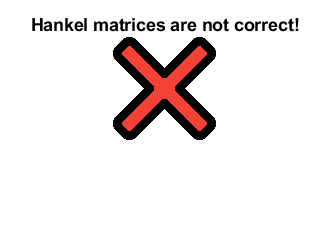

test_hankelmatrices(U_hankel, Y_hankel);

#### II. Compute L_32 from LQ factorization 

Compute the matrix` L_32 `with $\left\lbrack \begin{array}{c}
U_f \\
Z\\
Y_f 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
L_{11}  & 0 & 0\\
L_{21}  & L_{22}  & 0\\
L_{21}  & L_{32}  & L_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
Q_1^T \\
Q_2^T \\
Q_3^T 
\end{array}\right\rbrack$, $Z=\left\lbrack \begin{array}{c}
U_p \\
Y_p 
\end{array}\right\rbrack$ by adapting the code below. 

**Important**: Do **not** change the variable name (L_32`)`, otherwise the test-function will not work! 

Please write your implementation below: Do not hard-code your implementation.

% YOUR CODE HERE
L_32 = 0;

Test-function for L_32.

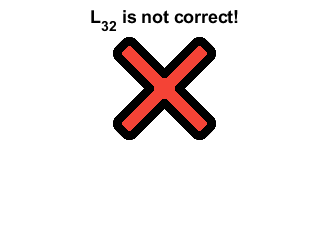

 test_L_32(L_32);

#### III.  Determine model order 

Plot the singular values of L_32 by adapting the code below. Motivate, which model order you would choose. Also, make sure to visualize the graph in a meaningufull manner, for example, by using a logarithmic representation and markers. Please note that a full graph includes titles and axis labels.

***Answer******: ***

*Motivate your choice of model order here.*

figure()
 % YOUR CODE HERE






#### IV. Compute the system matrices A and C

Compute the system matrices `A` and `C` by adapting the code below. For this exercise, we choose `n = 3. `

% DO NOT CHANGE THIS CODE
n = 3;

**Important**: Do **not** change the variable name (`A, C) `and the value `n = 4. O`therwise the test-function will not work! 

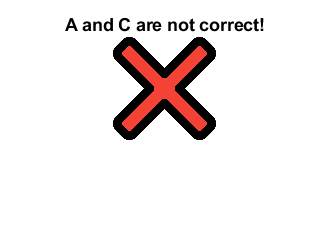

% YOUR CODE HERE
%computing A and C (lecture 10, slide 11)
C = 0;
A = 0;

test_A_C(A,C)

#### V. Compute x_0 and the system matrices B and D

Compute the `x_0 `and the system matrices `B` and `D` by adapting the code below. 

**Important**: Do **not** change the variable name (`x_0, B, D) `and the value `n = 3. O`therwise the test-function will not work! 

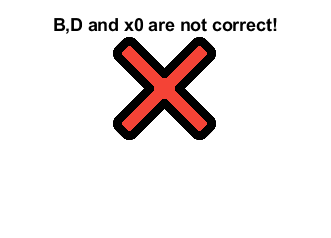

% YOUR CODE HERE


%unstack vector
x0 = 0;
B  = 0;
D  = 0;  

test_B_D_x0(B,D,x0)

#### VI. PO-MOESP

Combine the above segments in the function `pomoesp``,` such that it computes the matrices `A_po_moesp,B_po_moesp,C_po_moesp,D_po_moesp `and the initial condition `x0_po_moesp, `given the inputs `u_small, `the measured outputs `y_small `and the block size `s. `You can use the file `pomoesp.m` provided and then copy the whole function to the bottom of the live-script or write it in the live-script directly.  

Make sure to plot the singular values within the function and to provide the user with the option to enter the system order based on the plot of the singular values during run-time.  For this exercise, please choose `n = 3. `

**Important**: Do **not** change the variable name` (A_small,B_small,C_small,D_small,x0_small)` and give `n = 3` as an input`. O`therwise the test-function will not work! 

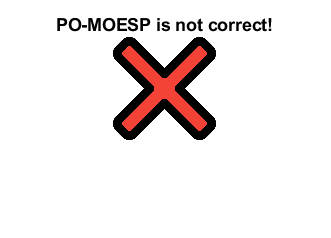

% DO NOT CHANGE THIS CODE
[A_small,B_small,C_small,D_small,x0_small] = pomoesp(u_small,y_small,s);

test_pomoesp(A_small,B_small,C_small,D_small,x0_small)

### c) Identification with PO-MOESP

#### I. POMOESP for training set

Apply the PO-MOESP algorithm on the training set with a training validation split of 2/3 - 1/3 to compute the matrices `A_po_moesp,B_po_moesp,C_po_moesp,D_po_moesp` as well as initial condition `x0_po_moesp.` Do not perform a validation step yet. Do **not** change the given training-validation split and block size `s = 100. `Please select `n = 4` during runtime. 

% DO NOT CHANGE THIS CODE
clear all
load iodata.mat
y = ymeas(1:9001);
u = u(1:9001);

s = 100; % to construct Hankel matrix with n < s << N
n = 4;

end_train = floor(length(y)*2/3);

%training data
y_train = y(1:end_train);
u_train = u(1:end_train);

%validation data
y_val = y(end_train+1:end);
u_val = u(end_train+1:end);

% YOUR CODE HERE


#### II. Simulate the system

Write a function `simsystem` that simulates a dynamic system given any input vector **u** and matrices `A_po_moesp,B_po_moesp,C_po_moesp,D_po_moesp` as well as initial condition `x0_po_moesp. `You can use the file `simsystem.m `provided and then copy the whole function to the bottom of the live-script or write it in the live-script directly. Simulate the system to compute measured and estimated outputs `y_train `and `yhat_po_moesp_train, `respectively. 

% YOUR CODE HERE


#### III. VAF and RMSE

Write a function `VAF `that computes the Variance Acocunted For (VAF) given the measured and estimated outputs `y_train `and `yhat_po_moesp_train, `respectively. You can use the file `VAF.m` provided and then copy the whole function to the bottom of the live-script or write it in the live-script directly.

% YOUR CODE HERE


Write a function `RMSE `that computes the root mean squared error (RMSE) given the measured and estimated outputs `y_train `and `yhat_po_moesp_train, `respectively. You can use the file `RMSE.m` provided and then copy the whole function to the bottom of the live-script or write it in the live-script directly.

% YOUR CODE HERE


#### IV. Validation Step

Test the PO-MOESP model on the validation data and compute the VAF and RMSE for the validation data. Plot your results with the code provided below.

% YOUR CODE HERE


Uncomment the code below to plot your results

% DO NOT CHANGE THIS CODE
% figure()
% plot(y_val)
% hold on
% plot(yhat_po_moesp_val)
% legend('truth','estimate')
% title(['PO-MOESP Validation'],['VAF = ',num2str(vaf_po_moesp_val),', RMSE = ',num2str(rmse_po_moesp_val)])


## Functions

### POMOESP()

% function [A,B,C,D,x0]=pomoesp(u,y,s,varargin)
% % Instructions:
% % Implement your subspace ID method here.
% % Use the following function inputs and outputs.
% 
% % Function INPUT 
% % u         system input (matrix of size N x m)
% % y         system output (matrix of size N x l)
% % s         block size (scalar)
% % varargin  optional input argument (for example for system order n, scalar) 
% %
% % Function OUTPUT
% % A         System matrix A (matrix of size n x n)
% % B         System matrix B (matrix of size n x m)
% % C         System matrix C (matrix of size l x n)
% % D         System matrix D (matrix of size l x m)
% % x0        Initial state (vector of size n x one)
% 
% % YOUR CODE HERE   
% 
% 
%     C = 0;
%     A = 0;
%     x0 = 0;
%     B  = 0;
%     D  = 0;      
% 
% end

### SIMSYSTEM()

% function y = simsystem(A,B,C,D,x0,u)
% % Instructions:
% % Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% % initial condition x(0)
% %
% %
% % Function INPUT
% % A system matrix (matrix of size n x n)
% % B system matrix (matrix of size n x m)
% % C system matrix (matrix of size l x n)
% % D system matrix (matrix of size l x m)
% % x0 initial state (vector of size n x one)
% % u system input (matrix of size N x m)
% %
% % Function OUTPUT
% % y system output (matrix of size N x l)
% 
% % YOUR CODE HERE
% 
%     y = 0;
% end

### VAF()

% function vaf = VAF(y,yhat)
% % Instructions:
% % Implement the calculation of the VAF here.
% %
% % Function INPUT
% % y    measured system output (matrix of size N x l)
% % yhat simulated system output (matrix of size N x l)
% %
% % Function OUTPUT
% % VAF Variance Accounted For (scalar)
% 
% % YOUR CODE HERE
%     vaf = 0;
% end

### RMSE()

% function rmse = RMSE(y,yhat)   
% % Instructions:
% % Implement the calculation of the RMSE here.
% %
% % Function INPUT
% % y    measured system output (matrix of size N x l)
% % yhat simulated system output (matrix of size N x l)
% %
% % Function OUTPUT
% % RMSE Root Mean Squared Error (scalar)
% 
% % YOUR CODE HERE
%     rmse = 0;
% end
